# Taller 1, puntos 7 a 9: Adaline y compuertas

Entradas en [0,1], salida deseada en [0,1], criterio de parada por error cuadratico

clear; close all; clc

## Parametros del modelo

alpha      = 0.05;
umbral     = 0.5;      % escalon para clasificar la salida lineal
salida     = [0 1];
error_min  = 1e-3;
max_epocas = 1000;
semilla    = 1;

## OR de 2 entradas

[X, d] = compuerta('OR', 2, salida);
[w, b, epocas, EC] = adaline(X, d, alpha, error_min, max_epocas, semilla);
epocas, EC_final = EC(end)

epocas = 104

EC_final = 0.1385

table(X(:,1), X(:,2), d, X*w' + b, predecir(X, w, b, umbral, salida), 'VariableNames', {'x1','x2','deseada','lineal','clasificada'})

ans = 4×5 table
    x1    x2    deseada    lineal     clasificada
    __    __    _______    _______    ___________

    0     0        0        0.2574         0     
    0     1        1       0.74947         1     
    1     0        1       0.73499         1     
    1     1        1        1.2271         1     


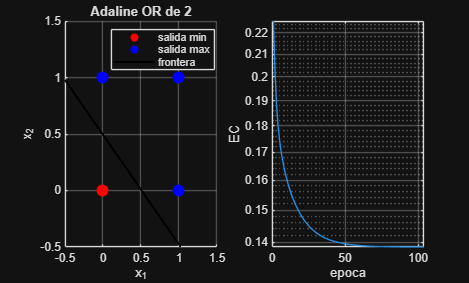


figure
subplot(1,2,1); graficar_frontera(X, d, w, b, umbral, 'Adaline OR de 2');
subplot(1,2,2); semilogy(EC); grid on; xlabel('epoca'); ylabel('EC')

## Reporte 1: todas las compuertas, incluida la XOR

casos = {'AND',2; 'AND',3; 'AND',4; 'OR',2; 'OR',3; 'OR',4; 'XOR',2};
R1 = table();
for c = 1:7
    [X, d] = compuerta(casos{c,1}, casos{c,2}, salida);
    [w, b, ep, EC] = adaline(X, d, alpha, error_min, max_epocas, semilla);
    acc = 100*mean(predecir(X, w, b, umbral, salida) == d);
    R1 = [R1; table(casos(c,1), casos{c,2}, ep, EC(end), acc, 'VariableNames', {'Compuerta','Entradas','Epocas','EC_final','Exactitud'})];
end
R1

R1 = 7×5 table
    Compuerta    Entradas    Epocas    EC_final    Exactitud
    _________    ________    ______    ________    _________

     {'AND'}        2          67      0.13846         100  
     {'AND'}        3         115       0.2953         100  
     {'AND'}        4          59      0.42917       93.75  
     {'OR' }        2         104       0.1385         100  
     {'OR' }        3          53      0.27266        87.5  
     {'OR' }        4          86       0.3697       93.75  
     {'XOR'}        2         128      0.55396          25  


## Reporte 2: efecto de alpha

alphas = [0.001 0.01 0.05 0.1 0.2 0.5 1];
R2 = table();
for c = 1:6
    [X, d] = compuerta(casos{c,1}, casos{c,2}, salida);
    for a = alphas
        [w, b, ep, EC] = adaline(X, d, a, error_min, max_epocas, semilla);
        acc = 100*mean(predecir(X, w, b, umbral, salida) == d);
        R2 = [R2; table(casos(c,1), casos{c,2}, a, ep, EC(end), acc, 'VariableNames', {'Compuerta','Entradas','Alpha','Epocas','EC_final','Exactitud'})];
    end
end
R2

R2 = 42×6 table
    Compuerta    Entradas    Alpha    Epocas     EC_final     Exactitud
    _________    ________    _____    ______    __________    _________

     {'AND'}        2        0.001     1000        0.12903        100  
     {'AND'}        2         0.01      327        0.12759        100  
     {'AND'}        2         0.05       67        0.13846        100  
     {'AND'}        2          0.1       27        0.15407        100  
     {'AND'}        2          0.2       47        0.19531        100  
     {'AND'}        2          0.5       20            0.5         75  
     {'AND'}        2            1     1000     4.9943e+05         50  
     {'AND'}        3        0.001     1000        0.25899       87.5  
     {'AND'}        3         0.01      282        0.25831        100  
     {'AND'}        3         0.05      115         0.2953        100  
     {'AND'}        3          0.1       71        0.35155        100  
     {'AND'}        3          0.2       43    

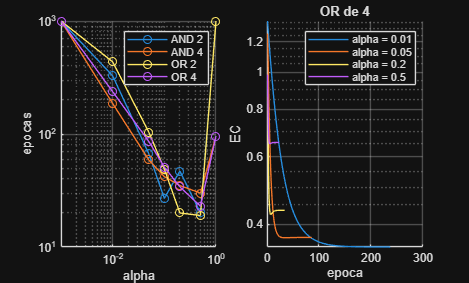


figure
subplot(1,2,1); hold on
for c = [1 3 4 6]
    m = strcmp(R2.Compuerta, casos{c,1}) & R2.Entradas == casos{c,2};
    plot(R2.Alpha(m), R2.Epocas(m), '-o', 'DisplayName', sprintf('%s %d', casos{c,1}, casos{c,2}));
end
set(gca, 'XScale', 'log', 'YScale', 'log'); grid on; legend; xlabel('alpha'); ylabel('epocas')
subplot(1,2,2); hold on
[X, d] = compuerta('OR', 4, salida);
for a = [0.01 0.05 0.2 0.5]
    [~, ~, ~, EC] = adaline(X, d, a, error_min, max_epocas, semilla);
    semilogy(EC, 'DisplayName', sprintf('alpha = %g', a));
end
set(gca, 'YScale', 'log'); grid on; xlim([0 300]); legend; xlabel('epoca'); ylabel('EC'); title('OR de 4')

## Reporte 3: tolerancia de parada y umbral (AND de 2)

Con una tabla de verdad el EC nunca llega a 1e-3, el que para es el cambio entre epocas

[X, d] = compuerta('AND', 2, salida);
R3 = table();
for tol = [1e-2 1e-3 1e-4 1e-5 1e-6]
    for u = [0.3 0.5 0.7]
        [w, b, ep, EC] = adaline(X, d, alpha, error_min, max_epocas, semilla, tol);
        acc = 100*mean(predecir(X, w, b, u, salida) == d);
        R3 = [R3; table(tol, u, ep, EC(end), acc, 'VariableNames', {'Tol_cambio','Umbral','Epocas','EC_final','Exactitud'})];
    end
end
R3

R3 = 15×5 table
    Tol_cambio    Umbral    Epocas    EC_final    Exactitud
    __________    ______    ______    ________    _________

        0.01       0.3         6      0.16221         75   
        0.01       0.5         6      0.16221        100   
        0.01       0.7         6      0.16221        100   
       0.001       0.3        13       0.1464         75   
       0.001       0.5        13       0.1464        100   
       0.001       0.7        13       0.1464        100   
      0.0001       0.3        34      0.13921        100   
      0.0001       0.5        34      0.13921        100   
      0.0001       0.7        34      0.13921        100   
       1e-05       0.3        54       0.1385        100   
       1e-05       0.5        54       0.1385        100   
       1e-05       0.7        54       0.1385        100   
       1e-06       0.3        67      0.13846        100   
       1e-06       0.5        67      0.13846        100   
       1e-06       0.7 

## Perceptron contra Adaline en las mismas compuertas

R4 = table();
for c = 1:7
    [X, d] = compuerta(casos{c,1}, casos{c,2}, [0 1]);
    [wp, bp, ep_p] = perceptron(X, d, 3, 0.05, 0.5, [0 1], 1000, 1);
    [wa, ba, ep_a] = adaline(X, d, 0.05, error_min, max_epocas, 1);
    R4 = [R4; table(casos(c,1), casos{c,2}, ep_p, 100*mean(predecir(X,wp,bp,0.5,[0 1]) == d), ...
                    ep_a, 100*mean(predecir(X,wa,ba,0.5,[0 1]) == d), ...
          'VariableNames', {'Compuerta','Entradas','Epocas_perc','Exact_perc','Epocas_ada','Exact_ada'})];
end
R4

R4 = 7×6 table
    Compuerta    Entradas    Epocas_perc    Exact_perc    Epocas_ada    Exact_ada
    _________    ________    ___________    __________    __________    _________

     {'AND'}        2              4           100            67            100  
     {'AND'}        3              7           100           115            100  
     {'AND'}        4              6           100            59          93.75  
     {'OR' }        2              2           100           104            100  
     {'OR' }        3              3           100            53           87.5  
     {'OR' }        4              5           100            86          93.75  
     {'XOR'}        2           1000            50           128             25  
